# Get Galaxy Profiles

## Stellar constats


c = 299792.458; % Speed of light in vacuum (Km/s)
% The positive charge RMS anomality of nucleons
B_sigma = 0.0000000061576779354155376441072376072967;

% The Star parameters
A_Sigma_star = 0.000000000000004495594326077030347123131497606; % The abnormality of Star


sig_stars = 0.945*15000;
sig_H = 103;

% The Gas parameters
A_Sigma_H = 0.99e-10; % The electron-proton anomality of GAS

% Estimation parameters

resolution=200;
nloops = 12;


## Test of M33 data

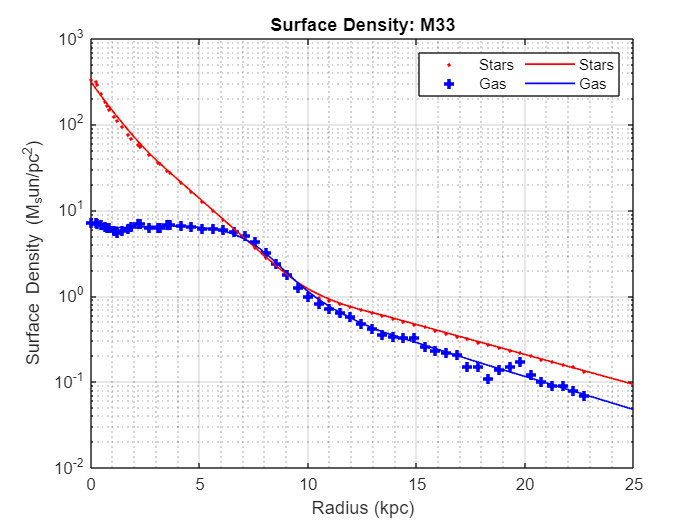

GalaxyName='M33';

VelMassData = [];

figure(1)
[r_data,V_obs,V_err,R_kpc,r_model,V_model,SigmaS,SigmaG,MStars,Mgas] = SRotation_curves(VelMassData,GalaxyName);

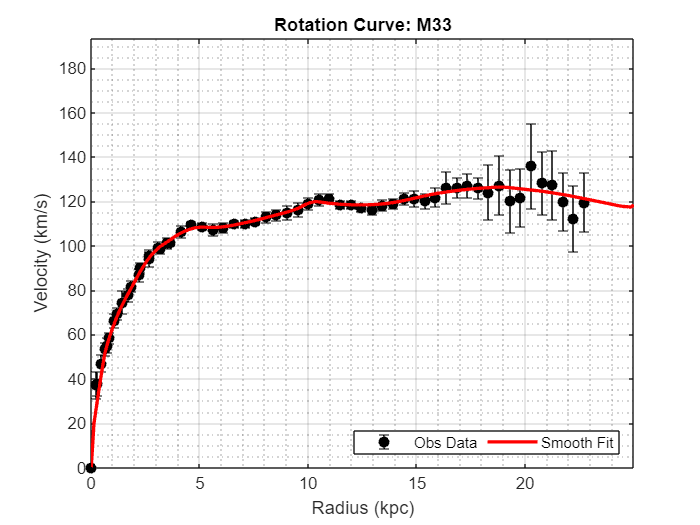


figure(2);
errorbar(r_data, V_obs, V_err, 'ko', 'MarkerFaceColor', 'k', 'DisplayName', 'Obs Data');
hold on;
plot(r_model, V_model, 'r-', 'LineWidth', 2, 'DisplayName', 'Smooth Fit');
xlabel('Radius (kpc)');
ylabel('Velocity (km/s)');
titles = append('Rotation Curve: ',GalaxyName);
title(titles);
legend('Location', 'southeast','NumColumns',2);
grid on;
grid minor;
xlim([0, max(r_model)]);
ylim([0, max(V_obs+3*V_err)]); % Enforce physical limits
hold off

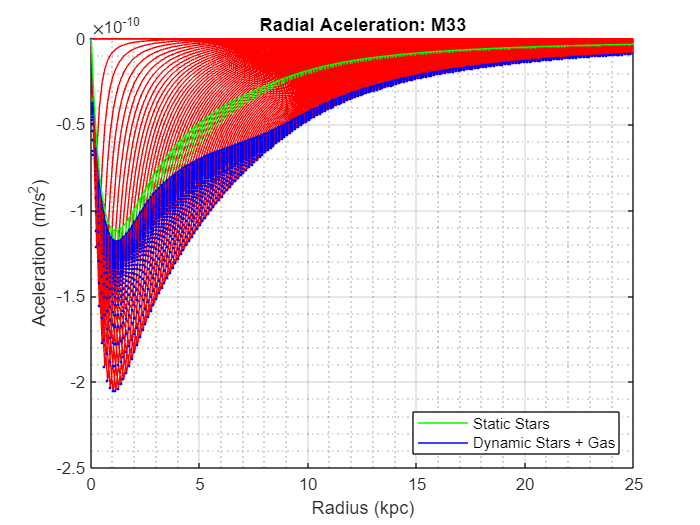

figure(3)
[V_tot,V_MOND,V_ele_G,V_ele,Zdist,StarProfile,GasZprofile,ax,ay] = fit_rotation_curveG(B_sigma,A_Sigma_star,A_Sigma_H,r_model,V_model,MStars,Mgas,sig_stars,sig_H,resolution,0,GalaxyName);

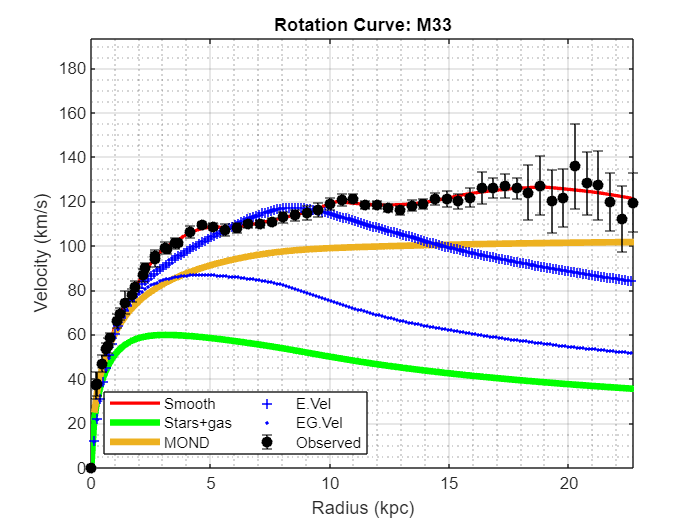

figure(4)
plotVelocities_SG(r_data,V_obs,V_err,r_model,V_model,V_tot,V_MOND,V_ele,V_ele_G,GalaxyName);

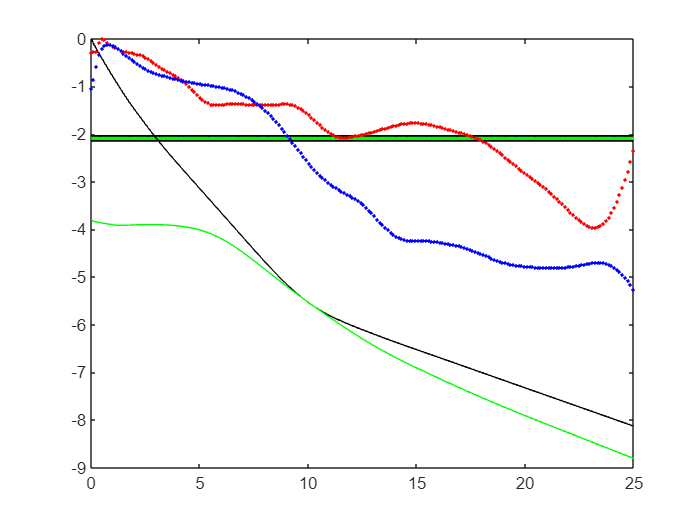

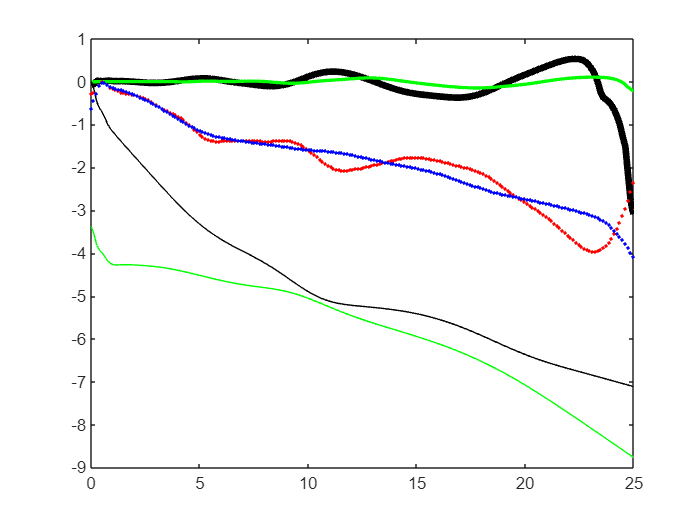

NSigma_S = MStars;
NSigma_H = Mgas;
NV_ele = V_ele;
testwhere=[];
for lps = 1:nloops
    ggain = 1.0-0.25*(mod(lps,3)>0) + 0.25*(mod(lps,3)==0);
    [Sigma_obs,Sigma_est,NSigma_S,NSigma_H,error,errorH,testwhere] = getNewDensities_v2(r_model,V_model,NV_ele,NSigma_S,NSigma_H,0.35,2.0*(lps>1),ggain,testwhere);

    figure(5)
    plot(r_model,5*error,"k-",'LineWidth', 4)
    hold on
    plot(r_model,5*errorH,"g-",'LineWidth', 2)
    plot(r_model,log(NSigma_S/max(NSigma_S)),"k-")
    plot(r_model,log(NSigma_H/max(NSigma_S)),"g-")
    plot(r_model,log(Sigma_obs/max(Sigma_obs)),"r.")
    plot(r_model,log(Sigma_est/max(Sigma_obs)),"b.")
    hold off

    figure(6)
    [V_tot,V_MOND,NV_ele_G,NV_ele,Zdist,StarProfile,GasZprofile,ax,ay] = fit_rotation_curveG(B_sigma,A_Sigma_star,A_Sigma_H,r_model,V_model,NSigma_S,NSigma_H,sig_stars,sig_H,resolution,lps,GalaxyName);

end

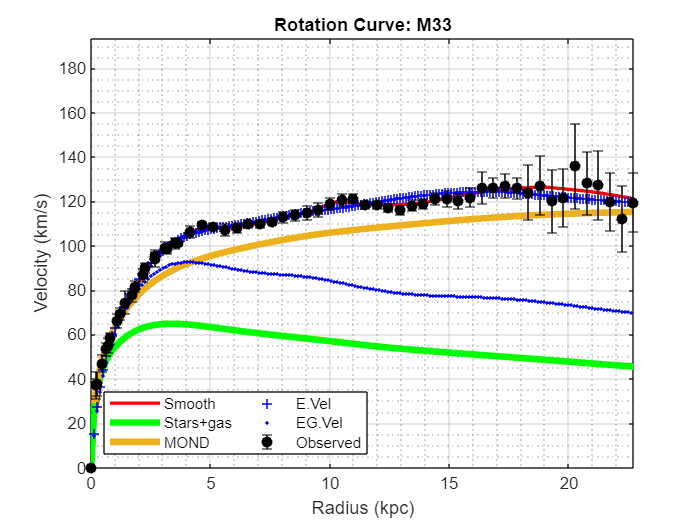

figure(7)
    plotVelocities_SG(r_data,V_obs,V_err,r_model,V_model,V_tot,V_MOND,NV_ele,NV_ele_G,GalaxyName);

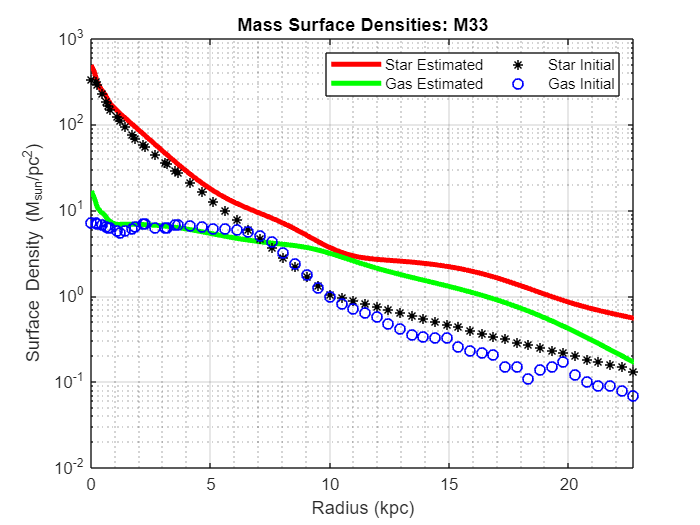

figure(8)
semilogy(r_model,NSigma_S,"r-", 'LineWidth', 3, 'DisplayName', 'Star Estimated')
hold on
semilogy(r_model,NSigma_H,"g-", 'LineWidth', 3, 'DisplayName', 'Gas Estimated')
semilogy(R_kpc,SigmaS,"k*", 'LineWidth', 1, 'DisplayName', 'Star Initial')
semilogy(R_kpc,SigmaG,"bo", 'LineWidth', 1, 'DisplayName', 'Gas Initial')
xlabel('Radius (kpc)');
ylabel('Surface Density (M_{sun}/pc^2)');
titles = append('Mass Surface Densities: ',GalaxyName);
title(titles);
legend('Location', 'northeast','NumColumns',2);
xlim([0, max(r_data)]);
grid on;
grid minor;
hold off


mascts = (1000^2)*2*pi*(r_model(3)-r_model(2));
totEstMASS = mascts*sum(MStars.*r_model)

totEstMASS = 5.0177e+09

totEstMASS2 = mascts*sum(NSigma_S.*r_model)

totEstMASS2 = 8.3311e+09

totEstMASS2/totEstMASS

ans = 1.6603

totEstGas = mascts*sum(NSigma_H.*r_model)

totEstGas = 2.8123e+09

TotGalMass = totEstMASS2+totEstGas

TotGalMass = 1.1143e+10

totObsEstRatioGas= sum(NSigma_H.*r_model)/sum(Mgas.*r_model)

totObsEstRatioGas = 1.6584

save("M33b_103_200.mat");